**1.**

***i***

f(x) = 1/(1-x^2)

f'(x) = 2x/(1-x^2)^2

f"(x) = (2+6x^2)/(1-x^2)^3

f(0) = 1/(1-0^2) = 1

f'(0) = 2*0/(1-0^2)^2 = 0

f"(0) = (2+6*0^2)/(1-0^2)^3 = 2

N= 2 for Talyor seires

Taylor series = f(0)+f'(0)(x-0)+f"(0)*(x-0)^2/2!

1+0+2/2(x^2) = **1+x^2**

***ii***

f'''(x) = 24(x^2+1)/(1-x^2)^4

x0, x1, x2 = 0

E2`(x``)` `=`` (`x `−` x0`)``(`x `−` x1)`(`x `−` x2`)`f^(2`+`1)(c) / (2`+`1)! = (x^3*24(c^2+1)/(1-c^2)^4) / 6

maximum value to estimate the upper bound would be c=0

so, E2(x) = 24 x^3 /6 = **4x^3**

**2.**

***i***

P4(x) = a0 + a1(x-x0) + a2(x-x0)(x-x1) +a3(x-x0)(x-x1)(x-x2)+a4(x-x0)(x-x1)(x-x2)(x-x4)

a0 = f(x0)

a1 = (f(x1)-f(x0))/(x1-x0)

a2 = ((f(x2)-f(x1))/(x2-x1)-(f(x1)-f(x0))/(x1-x0))/(x2-x0)

a3 = ((f(x3)-f(x2))/(x3-x2)-((f(x2)-f(x1))/x2-x1)-(f(x1)-f(x0))/(x1-x0))/(x2-x0))/(x3-x0)

a4 = ((f(x4)-f(x3))/(x4-x3)-((f(x3)-f(x2))/(x3-x2)-((f(x2)-f(x1))/x2-x1)-(f(x1)-f(x0))/(x1-x0))/(x2-x0))/(x3-x0))/(x4-x0)

***ii***

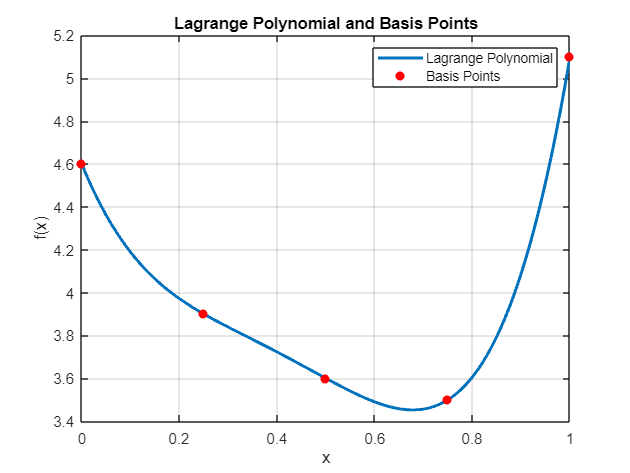

x_values = [0.0, 0.25, 0.50, 0.75, 1.0];
y_values = [4.6, 3.9, 3.6, 3.5, 5.1];
coefficients = polyfit(x_values, y_values, 4);

x_plot = linspace(0, 1, 1000);
y_plot = polyval(coefficients, x_plot);

figure;
plot(x_plot, y_plot, 'LineWidth', 2);
hold on;

scatter(x_values, y_values, 'r', 'filled');

title('Lagrange Polynomial and Basis Points');
xlabel('x');
ylabel('f(x)');
legend('Lagrange Polynomial', 'Basis Points');
grid on;
hold off;

**3.**

***i***

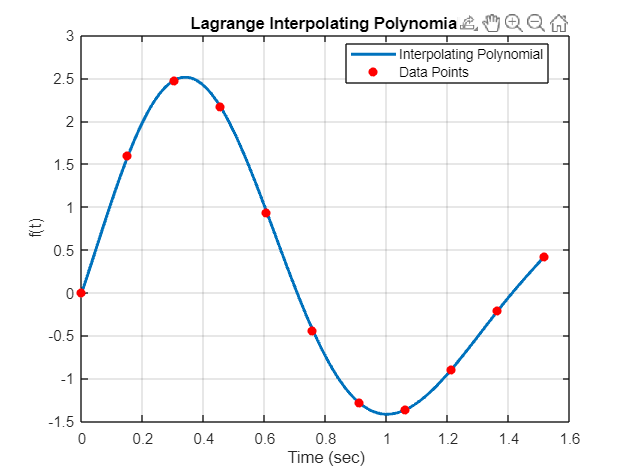

t = [0, 0.1515, 0.3030, 0.4545, 0.6061, 0.7576, 0.9091, 1.0606, 1.2121, 1.3636, 1.5152];
f_t = [0, 1.594, 2.475, 2.166, 0.939, -0.442, -1.285, -1.367, -0.894, -0.211, 0.417];
coefficients = polyfit(t, f_t, 10);

t_plot = linspace(0, 1.5152, 1000);
f_plot = polyval(coefficients, t_plot);

figure;
plot(t_plot, f_plot, 'LineWidth', 2);
hold on;
scatter(t, f_t, 'r', 'filled');
title('Lagrange Interpolating Polynomial');
xlabel('Time (sec)');
ylabel('f(t)');
legend('Interpolating Polynomial', 'Data Points', 'Location', 'Best');
grid on;
hold off;

***ii***

t_values = [0.17, 0.63, 0.95, 1.25];
for i = 1:length(t_values)
    fprintf('f(%.2f) = %.4f\n', t_values(i), double(subs(L, x, t_values(i))));
end

f(0.17) = 1.7565
f(0.63) = 0.7099
f(0.95) = -1.3791
f(1.25) = -0.7298


***Bonus:***

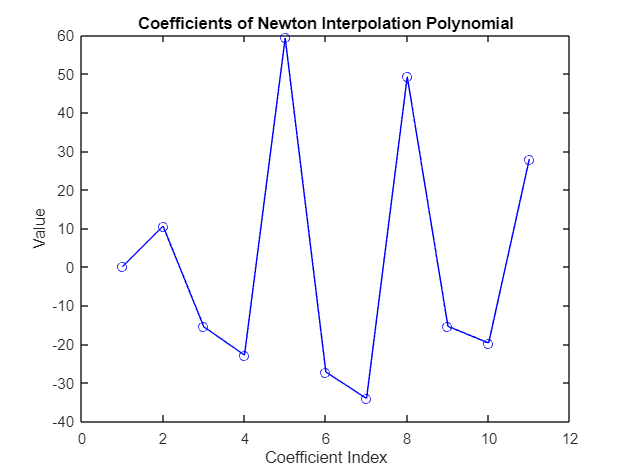

n = length(t);
D = zeros(n, n);
D(:,1) = f';

for j = 2:n
    for i = j:n
        D(i,j) = (D(i,j-1) - D(i-1,j-1)) / (t(i) - t(i-j+1));
    end
end

coefficients = diag(D);

plot(coefficients, 'bo-');
title('Coefficients of Newton Interpolation Polynomial');
xlabel('Coefficient Index');
ylabel('Value');